# **RRA**

# **Lab10 (Parteneriat cu laburile scrise de PETrascu)**

## **Reglare **$\mathcal{H}_{2}
$ (o sa fac si o recaliptulare la calcularea normei $\mathcal{H}_{2}
$ si $\mathcal{L}_{2}
$)

#### Pana sa intram in reglare ${\mathcal{H}}_2$, mai intai o sa vreau sa vorbesc despre norma ${\mathcal{L}}_2$ (spatiu Lebesgue) si ${\mathcal{H}}_2$ (spatiu Hardy)

Pentru **Matricea de Transfer (cazul MIMO)** definim $||G||_2 :={\left\lbrace \frac{1}{2\pi }\int_{-\infty }^{\infty } \mathrm{tr}\left\lbrack G\tilde{} \left(\mathrm{jw}\right)G\left(\mathrm{jw}\right)\right\rbrack \mathrm{dw}\right\rbrace }^{\frac{1}{2}}$ care se numeste norma ${\mathcal{L}}_2$


$$||G||_2 <\infty \Leftrightarrow G\in \mathcal{R}{\mathcal{L}}_2 {\left(s\right)}^{\mathrm{pxm}} \Leftrightarrow \left\lbrace \begin{array}{l}
G\left(s\right)\;\mathrm{nu}\;\mathrm{are}\;\mathrm{poli}\;\mathrm{pe}\;{\mathbb{C}}_0 \\
G\left(\infty \right)=0,\mathrm{adica}\;\mathrm{este}\;\mathrm{strict}\;\mathrm{proprie}
\end{array}\right.$$


S-ar putea rezolva norma 2 folosind **Teoria Reziduurilor**, cel mai bine folosim unele formule pe stare (Lyapunov)

Presupunem ca sistemul este luat aleator si este reprezentat intr-o stare minimala. Norma lui ${\mathcal{L}}_2$ este finita $\Leftrightarrow \left\lbrace \begin{array}{l}
D=0\\
A\;\mathrm{este}\;\mathrm{dihotomica}
\end{array}\right.$. In acest sens, sistemul se poate aduce la forma $G\left(s\right)=G_s \left(s\right)+G_a \left(s\right),\mathrm{unde}\;\left\lbrace \begin{array}{l}
G_s \left(s\right)\;\mathrm{are}\;\mathrm{polii}\;\mathrm{in}\;{\mathbb{C}}_- \;\left(\mathrm{este}\;\mathrm{stabil}\right)\;\mathrm{sau}\;G_s \left(s\right)\in \mathcal{R}{\mathcal{H}}_2 \\
G_a \left(s\right)\;\mathrm{are}\;\mathrm{polii}\;\mathrm{in}\;{\mathbb{C}}_+ \left(\mathrm{este}\;\mathrm{antistabil}\right)\;\mathrm{sau}\;G_a \left(s\right)\in \mathcal{R}{\mathcal{H}}_2^{\bot } 
\end{array}\right.$. Atunci are loc rezultatul: $||G||_2^2 =||G_s ||_2^2 +||G_a ||_2^2$. 

 O mica observatie: Stim ca $G_s \;\mathrm{si}\;G_a$ sunt ortogonale si ca $||\tilde{G} ||_2 =||G||_2$. In acest sens, daca $G_a$ este antistabil, asta inseamna ca $\tilde{G_a \left(s\right)} =G_a^T \left(-s\right)$ care este stabil. Asadar, putem rescrie egalitatea in felul irmator: $||G||_2^2 =||G_s ||_2^2 +||\tilde{G_a } ||_2^2$ si este suma de 2 stabile

#### Acum trebuie calculate cele 2 norme de tip ${\mathcal{H}}_2$. Cum facem asta? Uite aici:

**Pentru A stabil, norma 2 se calculeaza: **$||G||_2 ={\left\lbrack \mathrm{tr}\left(B^T \mathrm{QB}\right)\right\rbrack }^{\frac{1}{2}} ={\left\lbrack \mathrm{tr}\left({\mathrm{CPC}}^T \right)\right\rbrack }^{\frac{1}{2}} ,\mathrm{unde}\;P\;\mathrm{si}\;Q\;\mathrm{sunt}\;\mathrm{solutiile}\;\mathrm{unice}\;\mathrm{ale}\;\mathrm{ecuatiilor}\;\mathrm{Lyapunov}$


$$\left\lbrace \begin{array}{l}
\mathrm{AP}+{\mathrm{PA}}^T +{\mathrm{BB}}^T =0\\
A^T Q+\mathrm{QA}+C^T C=0
\end{array}\right.$$


**Pentru A instabil, norma 2 se calculeaza: **


$$||G||_2 ={\left\lbrack \mathrm{tr}\left(B^T \hat{Q} B\right)\right\rbrack }^{\frac{1}{2}} ={\left\lbrack \mathrm{tr}\left({C\hat{P} C}^T \right)\right\rbrack }^{\frac{1}{2}} ,\mathrm{unde}\;\hat{P} \;\mathrm{si}\;\hat{Q} \;\mathrm{sunt}\;\mathrm{solutiile}\;\mathrm{unice}\;\mathrm{ale}\;\mathrm{ecuatiilor}\;\mathrm{Lyapunov}$$


$\left\lbrace \begin{array}{l}
A\hat{P} +{\hat{P} A}^T -{\mathrm{BB}}^T =0\\
A^T \hat{Q} +\hat{Q} A-C^T C=0
\end{array}\right.$, unde tr(A) reprezinta suma elementelor de pe diagonala principala

Daca $\hat{P} \ge 0$, atunci perechea $\left(A,B\right)$ este controlabila

Daca $\hat{Q} \ge 0$, atunci perechea $\left(C,A\right)$ este observabila

## Acum intram in reglare ${\mathcal{H}}_2$

Fie sistemul generalizat $\left\lbrace \begin{array}{l}
\dot{x} =\mathrm{Ax}+B_1 u_1 +B_2 u_2 \\
y_1 =C_1 x+D_{11} u_1 +D_{12} u_2 \\
y_2 =C_2 x+D_{21} u_1 +D_{22} u_2 
\end{array}\right.$

Reprezentarea pe stare arata asa: $T=\left\lbrack \begin{array}{ccc}
A & B_1  & B_2 \\
C_1  & D_{11}  & D_{12} \\
C_2  & D_{21}  & D_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack$

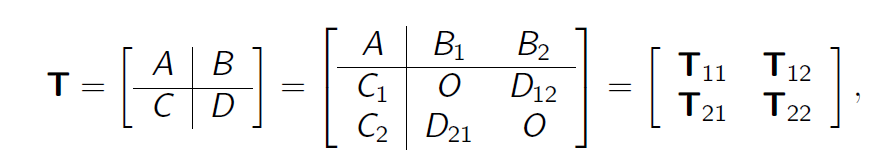

Problema optimala $\mathcal{H}_2$ arata asa: $\min_{K \text{ stabil}} ||TLFi(T,K)||_2$, unde $TLFI(T,K)=T_{cl}$ (In slide-urile de curs este notat $T_{y_1 u_1 }$)

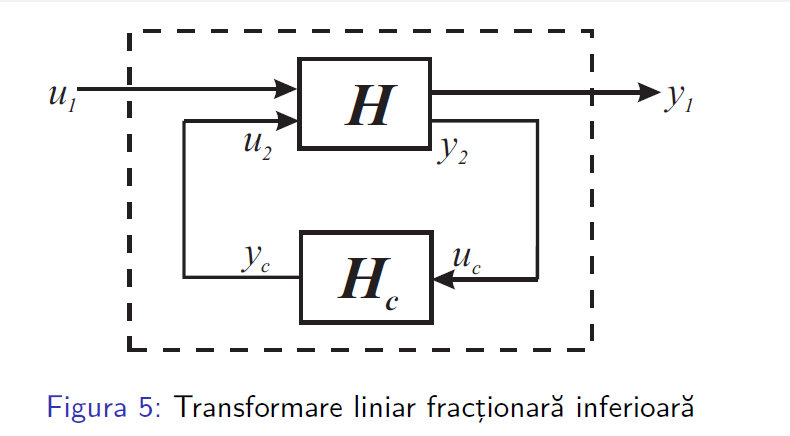


$$TLFi(T,K)=T_{11} + T_{12}K(I-T_{22}K)^{-1}T_{21}$$


Fie $K=\left\lbrack \begin{array}{cc}
A_K  & B_K \\
C_K  & D_k 
\end{array}\right\rbrack$. Trebuie sa existe ${\left(I-T_{22} K\right)}^{-1}$. Pentru a asigura buna definire, trebuie ca $\left\lbrack \begin{array}{cc}
I & -D_K \\
-D_{22}  & I
\end{array}\right\rbrack$ sa fie inversabil

Sa zicem reprezentarea pe stare $TLFi(T,K)=T_{cl}=$$\left\lbrack \begin{array}{cc}
A_{\mathrm{cl}}  & B_{\mathrm{cl}} \\
C_{\mathrm{cl}}  & D_{\mathrm{cl}} 
\end{array}\right\rbrack$

Ideea de baza este sa gasim un regulator $K$ astfel incat $\Lambda(A_{cl})\in \mathbb{C}_-$ (daca este satisfacuta asta, este stabilziator) si sa aiba $||T_{cl}||_2^2<\infty$, adica $\left\lbrace \begin{array}{l}
T_{\mathrm{cl}} \left(\infty \right)=0\\
T_{\mathrm{cl}} \left(s\right)\;\mathrm{sa}\;\mathrm{NU}\;\mathrm{aiba}\;\mathrm{poli}\;\mathrm{in}\;{\mathbb{C}}_0 
\end{array}\right.$. Sa detaliez la $T_{\mathrm{cl}} \left(\infty \right)=0$, practic $D_{\mathrm{cl}} =0$. Asta insemna ca $D_{11} +D_{12} D_K {\left(I-D_{22} D_K \right)}^{-1} D_{21} =0$ 

### Ce presupuneri facem:

- 
$$\left(A,B_2 \right)\;\mathrm{stabilizabil}$$


- 
$$\left(C_2 ,A\right)\;\mathrm{detectabil}$$


- $D_{11} =0$ pentru a asigura ca avem mereu solutie

- $D_K =0$ pentru a avea buna definire asigurata a $\mathrm{TLFi}$-ului si pentru a avea solutie EMAR

- $D_{22} =0$. De asta nu este neaparat nevoie, dar se poate presupune pentru a usura calculele. Asta zice ca $\mathrm{TLFi}$-u este strict propriu

**Prima si a treia presupunere ne zic ca norma 2 este finita si ca **$T_{\mathrm{cl}} \left(\infty \right)=D_{\mathrm{cl}} =0$**. Din pacate, aceste cerinte sunt DOAR**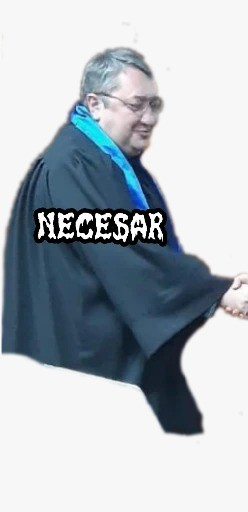** pentru a asigura solutia problemei **${\mathcal{H}}_2$

Care-i faza cu $D_{22} =0$:

Sa zicem ca avem $\tilde{T} =T-\left\lbrack \begin{array}{cc}
0 & 0\\
0 & D_{22} 
\end{array}\right\rbrack$

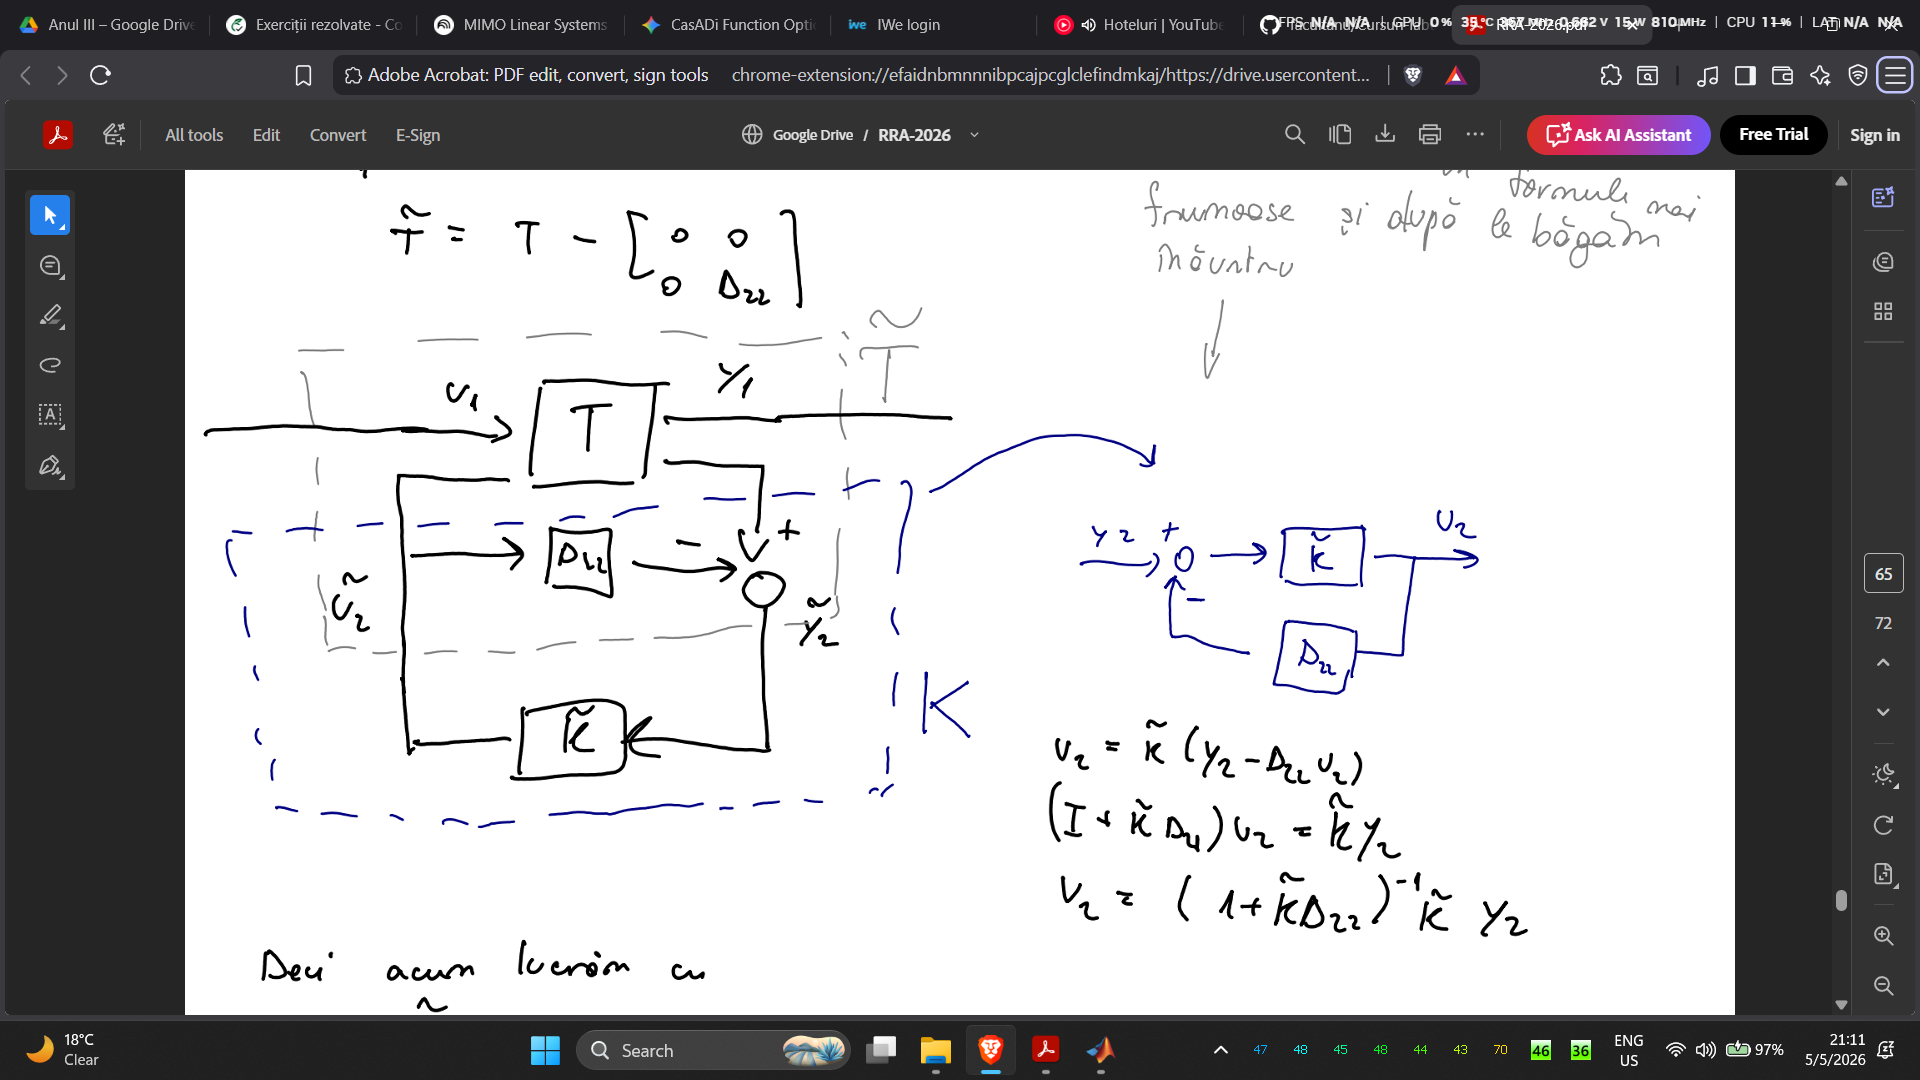

De aici scoatem ca $u_2 =\tilde{K} \left(y_2 -D_{22} u_2 \right)$. Vedem ca $u_2 ={\left(I+\tilde{K} D_{22} \right)}^{-1} \tilde{K} y_2$, cu $\tilde{K} D_{22}$ este strict propriu. ${\left(I+\tilde{K} D_{22} \right)}^{-1} \tilde{K} =K$. Ideea e ca ne reducem mult calculele aici

O sa reatasez T pentru a ne ajuta mai departe: $T=\left\lbrack \begin{array}{ccc}
A & B_1  & B_2 \\
C_1  & D_{11}  & D_{12} \\
C_2  & D_{21}  & D_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack$

Fie sistemu nostru $T$ cu 2 triplete Popov asociate:$\left\lbrace \begin{array}{l}
\Sigma_{12} =\left(A;B_2 ;\left\lbrack \begin{array}{cc}
C_1^T C_1  & C_1^T D_{12} \\
D_{12}^T C_1  & D_{12}^T D_{12} 
\end{array}\right\rbrack \right)\\
\Sigma_{21} =\left(A^T ;C_2^T ;\left\lbrack \begin{array}{cc}
B_1 B_1^T  & B_1 D_{21}^T \\
D_{21} B_1^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack \right)
\end{array}\right.$.* Practic astea sunt factorilzarile inner-outer pentru *$T_{12}$* si co-inner-outer pentru *$T_{21}$. La $\Sigma_{12}$ are sens forma. La $\Sigma_{21}$ pare mai ciudatica. De ce? Noi stim 2 chestii: $\left\lbrace \begin{array}{l}
\left(C_2 ,A\right)\;\mathrm{detectabil}\Rightarrow \left(A^T ,C_2^T \right)\;\mathrm{stabilizabil}\\
\Sigma =\left(A;B;\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \right),\mathrm{unde}\;Q=C^T C,R=D^T D\;\mathrm{si}\;L=C^T D
\end{array}\right.$. Practic la tripletul Popov $\Sigma_{21}$, $A=A^T \;\mathrm{si}\;B=C_2^T$. Asta inseamna ca $C=B_1^T \;\mathrm{si}\;D=D_{21}^T$ si se inlocuiesc in matrice.

Pornind de la cele 2 triplete Popov, facem urmatoarele presupuneri:

        **H1)** Stim deja ca $\left(A,B_2 \right)$ stabilizabil. Totodata, mai presupunem ca $R_{12} =D_{12}^T D_{12} >0$ are rang integ pe coloane si ca matricea $\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_2 \\
C_1  & D_{12} 
\end{array}\right\rbrack$ are rang intreg pe coloane, adica $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_2 \\
C_1  & D_{12} 
\end{array}\right\rbrack =n+m_2$, $\forall w\in \mathbb{R}$ (coloane aici). Prin asta se indeplinesc toate ipotezele de factorizare inner-outer.

        **H2)** Stim deja ca $\left(C_2 ,A\right)$ detectabil Totodata, mai presupunem ca $R_{21} =D_{21} D_{21}^T >0$ are rang integ pe linii si ca matricea $\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_1 \\
C_2  & D_{21} 
\end{array}\right\rbrack$ are rang intreg pe linii, adica $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_1 \\
C_2  & D_{21} 
\end{array}\right\rbrack =n+p_2$, $\forall w\in \mathbb{R}$ (linii aici)

Daca **H1) si H2)** au loc, atunci

- $\mathrm{EMAR}\left(\Sigma_{12} \right)=A^T X+\mathrm{XA}+Q-\left(\mathrm{XB}+L\right)R^{-1} \left(B^T X+L^T \right)$ are solutie stabilizatoare $X_s \ge 0$:$A^T X_s +X_s A+C^T C-\left(X_s B+C_1^T D_{12} \right){\left(D_{12}^T D_{12} \right)}^{-1} \left(B_2^T X_s +D_{12}^T C\right)=0$ si reacite stabilizatoare $F_s :={-R}^{-1} \left(B^T X+L^T \right)=$$-{\left(D_{12}^T D_{12} \right)}^{-1} \left(B_2^T X_s +D_{12}^T C\right)$

- $\mathrm{EMAR}\left(\Sigma_{21} \right)=A^T X+\mathrm{XA}+Q-\left(\mathrm{XB}+L\right)R^{-1} \left(B^T X+L^T \right)$ are solutie stabilizatoare $Y_s \ge 0$: $A^T Y_s +Y_s A+B_1 B_1^T -\left({Y_s C}_2^T +B_1 D_{21}^T \right){\left(D_{21} D_{21}^T \right)}^{-1} \left(C_2 Y_s +D_{21} B_1^T \right)=0$ si reactie stabilizatoare $K_s :={-R}^{-1} \left(B^T X+L^T \right)=-\left(D_{21} D_{21}^T \right)\left(C_2 Y_s +D_{21} B_1^T \right)$

- Regulatorul optimal si strict propriu in sens ${\mathcal{H}}_2$ este dat de $K_{\mathrm{opt}} =\left\lbrack \begin{array}{cc}
A+B_2 F_s +K_s^T C_2  & -K_s^T \\
F_s  & 0
\end{array}\right\rbrack$  $K\left(s\right)=\left\lbrack \begin{array}{cc}
A+\mathrm{BF}+LC+\mathrm{LDF} & -L\\
F & 0
\end{array}\right\rbrack ,\mathrm{unde}\;\left\lbrace \begin{array}{l}
\Lambda \left(A+\mathrm{BF}\right)\subset {\mathbb{C}}^- \\
\Lambda \left(A+\mathrm{LC}\right)\subset {\mathbb{C}}^- 
\end{array}\right.$. $D_{22}$ si $D_{11}$ si $D_K$ am zis ca sunt 0. ***Chestia asta merge DOAR DACA ***$D_{22} =0$. Daca am $D_{22} \not= 0$, atunci fac bucla de reactie dintre $K_{\mathrm{opt}} \left(s\right)\;\mathrm{si}\;D_{22}$

Valoarea optimala (minimala) a normei ${\mathcal{H}}_2$ este: $\min_{K \text{ stabil}} ||TLFi(T,K)||_2 = \min_{K \text{ stabil}} ||T_{cl}||_{2}=[tr(B_1^TX_sB_1) + tr(W_xY_sW_x^T)]^{\frac{1}{2}} = [tr(W_yX_sW_y^T) + (C_1Y_sC_1^T)]^{\frac{1}{2}$. Ok, dar cine sunt $\left\lbrace \begin{array}{l}
W_x \\
W_y 
\end{array}\right.$? Ele ies din Sistemul Kalman-Yakubovich-Popov(SKYP). Aici o sa presupunem ca $J=I$. Avem 2 SKYP-uri, unul pentru $\Sigma_{12}$ ai altul pentru $\Sigma_{21}$.

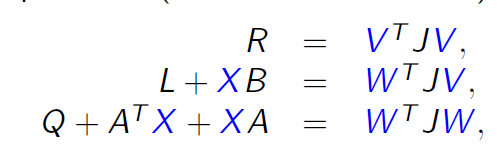

Am zis de la inceput ca luam $J=I$. Deci putem rescrie SKYP asa: $\left\lbrace \begin{array}{l}
R=V^T V\\
L+\mathrm{XB}=W^T V\\
A^T X+\mathrm{XA}+Q=W^T W
\end{array}\right.$

- Acum sa luam $\mathrm{SKYP}\left(\Sigma_{12} ,I\right)$. Avem $\left\lbrace \begin{array}{l}
D_{12}^T D_{12} =V_x^T V_x \\
C_1^T D_{12} +X_s B_2 =W_x^T V_x \\
C_1^T C_1 +A^T X_s +X_s A=W_x^T W_x 
\end{array}\right.$. Scoatem pe $V_x$ ca fiind factor cholesky din $D_{12}^T D_{12}$. De asemenea, noi stim cat este $F_s$. Totodata, stim asa:  $F=-V^{-1} W$, unde F este rectia stabilizatoare din $\mathrm{EMAR}\left(\Sigma \right)$. Asadar, putem scrie ca $F_s =-V_x^{-1} W_s$. Noi stim pe $V_x \;\mathrm{si}\;F_s$. Scoatem pe $W_s =-V_x F_s$

- Acum sa luam $\mathrm{SKYP}\left(\Sigma_{21} ,I\right)$. Avem $\left\lbrace \begin{array}{l}
D_{21} D_{21}^T =V_y^T V_y \\
B_1 D_{21}^T +Y_s C_2^T =W_y^T V_y \\
B_1 B_1^T +A^T Y_s +Y_s A=W_y^T W_y 
\end{array}\right.$. Scoatem pe $V_y$ ca fiind factor cholesky din $D_{21} D_{21}^T$. De asemenea, noi stim cat este $K_s$. Totodata, stim asa:  $F=-V^{-1} W$, unde F este rectia stabilizatoare din $\mathrm{EMAR}\left(\Sigma \right)$. Asadar, putem scrie ca $K_s =-V_y^{-1} W_y$. Noi stim pe $V_y \;\mathrm{si}\;K_s$. Scoatem pe $W_y =-V_y K_s$

## Laborator

Remarca: matricile sunt alese aleator, deci la executarea scriptului o sa dea rezultate diferite

clear
close all
clc

A = randn(5); % sistem cu 5 stari
B2 = randn(5,2); % m2 = 2
C2 = randn(2,5); % p2 = 2
D22 = randn(2,2); % Am zis ca nu e neaparat sa il iau 0 mereu. Vrem 0 pentru usurinta de calcul

B1 = randn(5,3); % m1 = 3
C1 = randn(3,5); % p1 = 3

D11 = zeros(3,3);
D12 = randn(3,2);
D21 = randn(2,3);

Acum ca ne-am definit sistemul, sa ne apucam sa rezolvam problema ${\mathcal{H}}_2$. Mai intai, trebuie sa vedem ca matricele $D_{12}$ are rang integ pe coloane, respectiv $D_{21}$ are rang intreg pe linii. *Probema:* nu am mereu garantie la matrici aleatoare ca o sa imi iasa cu rang intreg pe linii/coloane

D21

D21 =    -0.4189    0.8998    1.0294
   -0.1403   -0.3001   -0.3451


rank(D21) % se poate vedea ca matricea are rang intreg pe linii

ans = 2

D12

D12 =    -0.6086   -1.3429
   -1.2226   -1.0322
    0.3165    1.3312


rank(D12) % se poate vedea ca am rang intreg pe coloane

ans = 2

Acum verific daca $\left(A,B_2 \right)$ este stabilizabil si ca $\left(C_2 ,A\right)$ este detectabil. Cel mai ok ne uitam la zerourile de transmisie (bine, o sa vedem ca sistemul $\left(A,B_2 ,C_2 ,D_{22} \right)$ este minimal, deci zerouri de transmisie = zerouri de invarianta)

tzero(A,B2,[],[]) % controlabil, deci si stabilizabil


ans =

  0×1 empty double column vector



tzero(A,[],C2,[]) % observabil, deci si detectabil


ans =

  0×1 empty double column vector



Acum trebuie sa vedem ca rangul matricilor $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_2 \\
C_1  & D_{12} 
\end{array}\right\rbrack =n+m_2$, $\forall w\in \mathbb{R}$ si $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_1 \\
C_2  & D_{21} 
\end{array}\right\rbrack =n+p_2$, $\forall w\in \mathbb{R}$. Daca sunt goale, atunci nu inseamna neaparat ca au rang intreg pe coloane

tzero(A,B2,C1,D12) % Cu asta ne asiguram ca nu pica rangul matricii asteia


ans =

  0×1 empty double column vector



tzero(A,B1,C2,D21) % La fel, sa nu pice rangul undeva


ans =

  0×1 empty double column vector



Acum verificam rangul matricilor si ne asiguram ca $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_2 \\
C_1  & D_{12} 
\end{array}\right\rbrack =n+m_2$, $\forall w\in \mathbb{R}$ si $\mathrm{rang}\;\left\lbrack \begin{array}{cc}
A-\mathrm{jwI} & B_1 \\
C_2  & D_{21} 
\end{array}\right\rbrack =n+p_2$, $\forall w\in \mathbb{R}$

rank([A,B2;C1,D12]) % 5 stari si m2 = 2

ans = 7

rank([A,B1;C2,D21]) % 5 stari si p2 = 2

ans = 7

**Cu astea tin ipotezele. Adica putem rezolva cu EMAR**

Mai intati ne uitam la tripletul Popov $\Sigma_{12} =\left(A;B_2 ;\left\lbrack \begin{array}{cc}
C_1^T C_1  & C_1^T D_{12} \\
D_{12}^T C_1  & D_{12}^T D_{12} 
\end{array}\right\rbrack \right)$

Q12 = C1' * C1

Q12 =     5.2224   -4.0024   -1.2169    0.9295    0.6999
   -4.0024    7.8843    2.2321   -3.1544   -0.8119
   -1.2169    2.2321    3.3753   -4.1109   -0.4140
    0.9295   -3.1544   -4.1109    5.2224    0.4726
    0.6999   -0.8119   -0.4140    0.4726    0.1209


L12 = C1' * D12

L12 =    -2.2442   -1.2161
    3.9138    5.3278
    1.0467    2.4433
   -1.4314   -3.5947
   -0.4219   -0.4771


R12 = D12' * D12

R12 =     1.9653    2.5005
    2.5005    4.6408


Acum vedem tripletul Popov $\Sigma_{21} =\left(A^T ;C_2^T ;\left\lbrack \begin{array}{cc}
B_1 B_1^T  & B_1 D_{21}^T \\
D_{21} B_1^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack \right)$

Q21 = B1 * B1'

Q21 =     7.9910   -3.1254   -5.0530   -3.3334   -3.1976
   -3.1254    1.4740    2.2330    1.3675    1.2395
   -5.0530    2.2330    3.4989    2.0466    1.9538
   -3.3334    1.3675    2.0466    1.7878    1.5026
   -3.1976    1.2395    1.9538    1.5026    1.3573


L21 = B1 * D21'

L21 =     1.9848   -0.7127
   -1.3450    0.3675
   -1.9408    0.6161
   -0.6535    0.0938
   -0.6257    0.1795


R21 = D21 * D21'

R21 =     2.0448   -0.5665
   -0.5665    0.2288


Acum aflam de la $\Sigma_{12} =\left(A;B_2 ;\left\lbrack \begin{array}{cc}
C_1^T C_1  & C_1^T D_{12} \\
D_{12}^T C_1  & D_{12}^T D_{12} 
\end{array}\right\rbrack \right)$ $X_s \;\mathrm{si}\;F_s$

[Xs,Fs,spectrus12] = icare(A,B2,Q12,R12,L12)

Xs =    16.7987  -12.4916    1.5169  -14.4783  -24.0990
  -12.4916   11.5903   -3.6821    7.0676   12.1485
    1.5169   -3.6821    3.4720    2.8363    0.9745
  -14.4783    7.0676    2.8363   28.3900   29.2237
  -24.0990   12.1485    0.9745   29.2237   70.3221


Fs =     6.6231   -7.7418    3.4882  -10.7247   -7.9218
   -4.3428    6.3636   -1.9868    5.1238    2.2252


spectrus12 =   -0.4545 + 1.4504i
  -0.4545 - 1.4504i
  -0.6478 + 0.0000i
  -2.3205 + 0.0000i
  -4.5839 + 0.0000i


Fs = -Fs; % chestia asta pentru reactie pozitiva
eig(A + B2*Fs)

ans =   -4.5839 + 0.0000i
  -2.3205 + 0.0000i
  -0.6478 + 0.0000i
  -0.4545 + 1.4504i
  -0.4545 - 1.4504i


eig(Xs) % verificam ca solutia Riccati este pozitiv semi-definita

ans =     0.0004
    1.8203
   13.6980
   16.2006
   98.8536


Acum aflam de la $\Sigma_{21} =\left(A^T ;C_2^T ;\left\lbrack \begin{array}{cc}
B_1 B_1^T  & B_1 D_{21}^T \\
D_{21} B_1^T  & D_{21} D_{21}^T 
\end{array}\right\rbrack \right)$ pe $Y_s \;\mathrm{si}\;K_s$

[Ys,Ks,spectrus21] = icare(A',C2',Q21,R21,L21)

Ys =     2.3484   -0.3441   -1.2594   -1.0471   -0.0069
   -0.3441    8.9923   -2.6121    9.3430   -0.4145
   -1.2594   -2.6121    1.7586   -2.0742    0.2039
   -1.0471    9.3430   -2.0742   10.3122   -0.4527
   -0.0069   -0.4145    0.2039   -0.4527    0.1933


Ks =     3.1945    2.6505   -3.5493    2.5960   -1.7562
   11.2256   -4.4250   -6.9861   -8.7557   -4.2661


spectrus21 =   -0.5577 + 1.5618i
  -0.5577 - 1.5618i
  -1.3498 + 0.0000i
  -2.2865 + 0.0000i
 -11.4313 + 0.0000i


Ks = -Ks'; % negarea am zis de ce. Transpunerea este de la dualitate (recomand revedere curs TSA)
eig(A + Ks*C2) % na

ans =  -11.4313 + 0.0000i
  -0.5577 + 1.5618i
  -0.5577 - 1.5618i
  -2.2865 + 0.0000i
  -1.3498 + 0.0000i


eig(Ys)

ans =     0.0083
    0.1835
    0.3236
    3.4077
   19.6817


Partea 1 din teorema merge

K_opt = ss(A + B2*Fs + Ks*C2, -Ks, Fs, 0) % cand D22 = 0


K_opt =
 
  A = 
            x1       x2       x3       x4       x5
   x1    1.878   -10.98   0.7181   -7.851    15.59
   x2     9.83   -7.511    1.481   -18.82   -12.33
   x3   0.7384     1.72    1.044    4.427   -12.59
   x4     6.09    1.351   0.3782   -13.98   -17.56
   x5    2.368  -0.4948    1.837    1.048   -8.514
 
  B = 
           u1      u2
   x1   3.194   11.23
   x2   2.651  -4.425
   x3  -3.549  -6.986
   x4   2.596  -8.756
   x5  -1.756  -4.266
 
  C = 
           x1      x2      x3      x4      x5
   y1  -6.623   7.742  -3.488   10.72   7.922
   y2   4.343  -6.364   1.987  -5.124  -2.225
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


K_opt_h2 = feedback(K_opt,D22) % cand D22 != 0


K_opt_h2 =
 
  A = 
           x1      x2      x3      x4      x5
   x1   42.91   -46.3   25.28  -93.06  -62.69
   x2   18.59  -23.14   4.835  -25.01  -10.37
   x3  -34.76    35.5  -19.45   73.34   47.66
   x4   6.527  -9.553  -1.817  0.7209   5.891
   x5  -16.69   17.02  -9.307   38.95   25.24
 
  B = 
           u1      u2
   x1   3.194   11.23
   x2   2.651  -4.425
   x3  -3.549  -6.986
   x4   2.596  -8.756
   x5  -1.756  -4.266
 
  C = 
           x1      x2      x3      x4      x5
   y1  -6.623   7.742  -3.488   10.72   7.922
   y2   4.343  -6.364   1.987  -5.124  -2.225
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


T = ss(A,[B1,B2],[C1;C2],[D11,D12;D21,D22]); % T nostru original
T_cl = lft(T,K_opt_h2)


T_cl =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10
   x1     0.6125    -0.993    0.1992    0.9421    0.1202     6.938    -8.877     3.475     -10.1    -6.531
   x2   -0.05489     0.975    -1.521    0.3005    0.5712     8.546    -11.34     4.186    -11.84    -7.113
   x3     -1.119   -0.6407   -0.7236   -0.3731    0.4128    -2.032      2.63    -1.011     2.912     1.842
   x4    -0.6264     1.809   -0.5933    0.8155    -0.987      3.46    -4.466     1.724    -4.977    -3.165
   x5     0.2495     -1.08    0.4013    0.7989    0.7596   -0.1618    0.4959  -0.01364   -0.1927    -0.514
   x6      5.673     1.115     2.956    -1.306       -22     1.878    -10.98    0.7181    -7.851     15.59
   x7     -1.338    -2.851     1.185     7.278      5.79      9.83    -7.511     1.481    -18.82    -12.33
   x8     -3.889    0.2694    -2.778    -1.888     14.84    0.7384      1.72     1.044     4.427    -12.59
   x9     -3.256    

eig(T_cl.A)

ans =  -11.4313 + 0.0000i
  -4.5839 + 0.0000i
  -0.5577 + 1.5618i
  -0.5577 - 1.5618i
  -0.4545 + 1.4504i
  -0.4545 - 1.4504i
  -2.3205 + 0.0000i
  -2.2865 + 0.0000i
  -0.6478 + 0.0000i
  -1.3498 + 0.0000i


spectrus21

spectrus21 =   -0.5577 + 1.5618i
  -0.5577 - 1.5618i
  -1.3498 + 0.0000i
  -2.2865 + 0.0000i
 -11.4313 + 0.0000i


spectrus12 % respecta principuil separatiei Kalman asta

spectrus12 =   -0.4545 + 1.4504i
  -0.4545 - 1.4504i
  -0.6478 + 0.0000i
  -2.3205 + 0.0000i
  -4.5839 + 0.0000i


norm(T_cl,2) % norma 2 a lui TLFi(T,K)

ans = 56.2734

Verificam cu formula ca astea e ok

$V_x^T V_x =D_{12}^T D_{12}$.

Vx = chol(D12' * D12,'lower')'

Vx =     1.4019    1.7837
         0    1.2080


norm(D12' * D12 - Vx' * Vx) % paranoia lui Andrei cu chol:)))

ans = 2.2204e-16


$$V_y^T V_y =D_{21} D_{21}^T$$


Vy = chol(D21 * D21', 'lower')'

Vy =     1.4299   -0.3961
         0    0.2681


norm(D21 * D21' - Vy' * Vy) % paranoia lui Andrei cu chol:)))

ans = 4.4409e-16

Acum scot $W_x =-V_x F_s$

Wx = -Vx * Fs

Wx =     1.5386    0.4975    1.3462   -5.8956   -7.1365
   -5.2462    7.6873   -2.4001    6.1896    2.6880


Acum scot $W_y =-V_y K_s^T$

Wy = -Vy * Ks' % transpun ca sa aiba sens inmultirea matriceala (e practic Ks din EMAR netranspus)

Wy =     0.1210    5.5430   -2.3077    7.1807   -0.8213
    3.0100   -1.1865   -1.8733   -2.3477   -1.1439


Acum vedem ambele formule pentru problema noastra ${\mathcal{H}}_2$: $\min_{K \text{ stabil}} ||TLFi(T,K)||_2 = \min_{K \text{ stabil}} ||T_{cl}||_{2}=[tr(B_1^TX_sB_1) + tr(W_xY_sW_x^T)]^{\frac{1}{2}} = [tr(W_yX_sW_y^T) + (C_1Y_sC_1^T)]^{\frac{1}{2}$

norma2_manual_1 = sqrt(trace(B1' * Xs * B1) + trace(Wx * Ys * Wx'))

norma2_manual_1 = 56.2734

norma2_manual_2 = sqrt(trace(Wy * Xs * Wy') + trace(C1 * Ys * C1'))

norma2_manual_2 = 56.2734